# Option 1 center of mass

a test array

F = zeros(16,10);
F(14,5) = 100;
F(3,8) = 12;
%F(16,10) = 160;
%F(16,10) = 160;
% global sum of F
Ft = sum(F(:))

Ft = 112

% coordinates of F centroid
cy = sum((1:size(F,1)).'.*sum(F,2))/Ft

cy = 12.8214

cx = sum((1:size(F,2)).*sum(F,1))/Ft

cx = 5.3214

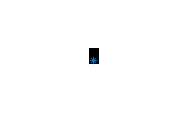

% visualize the result
imshow(F,[]); hold on
plot(cx,cy,'*','markersize',5)
hold off


% xlim([0 160])
% ylim([0 160])

## Option 2 center of force

fid = fopen('20220427T131641-2d.csv');
fOutput = fopen('20220427T131641-2d.csv');
tline = fgetl(fid);

Error using fgets
Invalid file identifier. Use fopen to generate
a valid file identifier.

Error in fgetl (line 32)
[tline,lt] = fgets(fid);

while ischar(tline)
    disp(tline)
    tline = fgetl(fid);
    if contains(tline, 'DISCLAIMER')
        break,
    end
    fopen(fOutput,'%s/n', tline);
end
fclose(fid);
fclose(fOutput);


% reshape and crop off NaNs
F = reshape([F; F(17,:)],17,10,[]);
F = F(1:end-1,:,:);
% for sake of demonstration, just pick two pages
F = F(:,:,370:371)
szf = size(F);
% global sum of F for all pages
Ft = sum(sum(F,1),2)
% coordinates of F centroid
cy = sum((1:szf(1)).'.*sum(F,2))./Ft
cx = sum((1:szf(2)).*sum(F,1))./Ft
imshow(F,[]); hold on
plot(cx,cy,'*','markersize',8)
hold off

## option 3 center of point

% read the file
% this is being done by lazy array expansion, which could be improved
fid = fopen('20220427T131641-2d.csv');
columns = 10;
F = [];
t = [];
while ~feof(fid)
    thislineraw = fopen(fid);
    
    % try to get a line
    thisline = sscanf(thislineraw,'%f,',[1 columns]);
    
    if isnumeric(thisline) && numel(thisline) == columns
        % if it's a numeric vector with 10 elements, it's data
        F = [F; thisline]; %#ok<*AGROW>
        continue;
    end
    
    % if it's not, then it's a block header
    % i don't know if it's needed, but for example, 
    % i'm going to get the timestamps in vector t
    % if timestamps aren't needed, this part can be omitted
    thisline = regexp(thislineraw,': (\d+\.\d+),+$','tokens');
    if ~isempty(thisline)
        t = [t; str2double(thisline{1}{1})];
    end	
end
% reshape F
F = reshape(F,16,10,[]);
% for sake of demonstration, just pick two pages
F = F(:,:,370:371)
szf = size(F);
% global sum of F for all pages
Ft = sum(sum(F,1),2)
% coordinates of F centroid
% need to use bsxfun() for array expansion prior to R2016b
cy = sum(bsxfun(@times,(1:szf(1)).',sum(F,2)))./Ft
cx = sum(bsxfun(@times,(1:szf(2)),sum(F,1)))./Ft